# Polynomial Trajectory analysis

## Quintic Polynomial trajectory

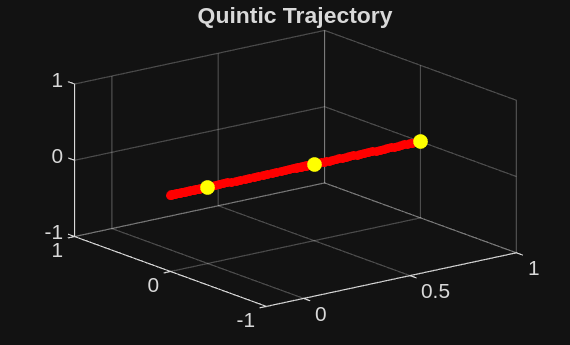

a_conditions = [
    0 0 0;
    0 0 0;
    0 0 0;
];

b_conditions = [
    0.5 0 0;
    0.1 0 0;
    0 0 0;
];

c_conditions = [
    1 0 0;
    0 0 0;
    0 0 0;
];

durationab = 2.0;
durationbc = 2.0;

[Xab,Yab,Zab,delta_tab,x_coeffs_ab,y_coeffs_ab,z_coeffs_ab] = quinticPolynomialTrajectory(a_conditions,b_conditions,durationab);
[Xbc,Ybc,Zbc,delta_tbc,x_coeffs_bc,y_coeffs_bc,z_coeffs_bc] = quinticPolynomialTrajectory(b_conditions,c_conditions,durationbc);

combinedX = [Xab; Xbc];
combinedY = [Yab; Ybc];
combinedZ = [Zab; Zbc];

figure = figure1;
scatter3(combinedX,combinedY,combinedZ,15,"red","filled");
title('Quintic Trajectory');
hold on;

scatter3(a_conditions(1,1),a_conditions(1,2),a_conditions(1,3),40,"yellow","filled");
scatter3(b_conditions(1,1),b_conditions(1,2),b_conditions(1,3),40,"yellow","filled");
scatter3(c_conditions(1,1),c_conditions(1,2),c_conditions(1,3),40,"yellow","filled");
hold off;

### Now get velocity and acceleration

velocity = coeff(2) + 2coeff(3)*t + 3coeff(4)*t^2 + 4coeff(5)t^3 + 5coeff(6)t^4

acceleration = 2coeff(3) + 6coeff(4)*t + 12coeff(5)t^2 + 20coeff(6)t^3

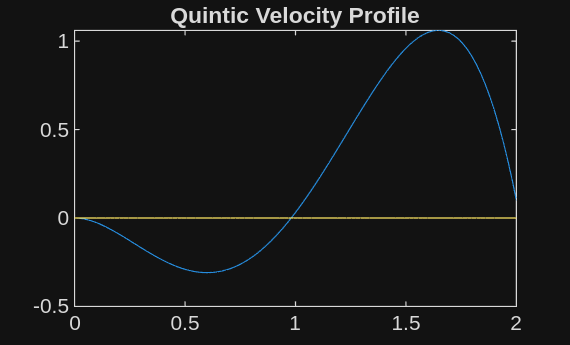


xVel_ab = x_coeffs_ab(2) + 2*x_coeffs_ab(3)*delta_tab + 3*x_coeffs_ab(4)*(delta_tab.^2) + 4*x_coeffs_ab(5)*(delta_tab.^3) + 5*x_coeffs_ab(6)*(delta_tab.^4);
yVel_ab = y_coeffs_ab(2) + 2*y_coeffs_ab(3)*delta_tab + 3*y_coeffs_ab(4)*(delta_tab.^2) + 4*y_coeffs_ab(5)*(delta_tab.^3) + 5*y_coeffs_ab(6)*(delta_tab.^4);
zVel_ab = z_coeffs_ab(2) + 2*z_coeffs_ab(3)*delta_tab + 3*z_coeffs_ab(4)*(delta_tab.^2) + 4*z_coeffs_ab(5)*(delta_tab.^3) + 5*z_coeffs_ab(6)*(delta_tab.^4);

figure2 = figure;
plot(delta_tab,xVel_ab);
hold on;
plot(delta_tab,yVel_ab);
plot(delta_tab,zVel_ab);
title("Quintic Velocity Profile");
hold off;


figure(figure1);

Unable to use a value of type string as an index.

figure appears to be both a function and a variable. If this is unintentional, use 'clear figure' to remove the variable 'figure' from the workspace.

hold on;
Vab = [xVel_ab(end) yVel_ab(end) zVel_ab(end)];
quiver3(b_conditions(1,1),b_conditions(1,2),b_conditions(1,3),Vab(1),Vab(2),Vab(3),0.5,'filled',"LineWidth",2);
hold off;

% also acceleration
xAcc_ab = 2*x_coeffs_ab(3) + 6*x_coeffs_ab(4)*delta_tab + 12*x_coeffs_ab(5)*(delta_tab.^2) + 20*x_coeffs_ab(6)*(delta_tab.^3);
yAcc_ab = 2*y_coeffs_ab(3) + 6*y_coeffs_ab(4)*delta_tab + 12*y_coeffs_ab(5)*(delta_tab.^2) + 20*y_coeffs_ab(6)*(delta_tab.^3);
zAcc_ab = 2*z_coeffs_ab(3) + 6*z_coeffs_ab(4)*delta_tab + 12*z_coeffs_ab(5)*(delta_tab.^2) + 20*z_coeffs_ab(6)*(delta_tab.^3);

figure5 = figure;
plot(delta_tab,xAcc_ab);
hold on;
plot(delta_tab,yAcc_ab);
plot(delta_tab,zAcc_ab);
title("Quintic Acceleration Profiles");
hold off;

## Cubic Polynomial Trajectory

[cubicXab,cubicYab,cubicZab,cubic_delta_t_ab,cubic_x_coeffs_ab,cubic_y_coeffs_ab,cubic_z_coeffs_ab] = cubicPolynomialTrajectory(a_conditions(1:2,:),b_conditions(1:2,:),durationab);
[cubicXbc,cubicYbc,cubicZbc,cubic_delta_t_bc,cubic_x_coeffs_bc,cubic_y_coeffs_bc,cubic_z_coeffs_bc] = cubicPolynomialTrajectory(b_conditions(1:2,:),c_conditions(1:2,:),durationbc);

combined_cubic_Xab = [cubicXab; cubicXbc];
combined_cubic_Yab = [cubicYab; cubicYbc];
combined_cubic_Zab = [cubicZab; cubicZbc];

figure3 = figure;
scatter3(combined_cubic_Xab,combined_cubic_Yab,combined_cubic_Zab,15,"red",'filled');
hold on;
scatter3(a_conditions(1,1),a_conditions(1,2),a_conditions(1,3),36,"yellow","filled");
scatter3(b_conditions(1,1),b_conditions(1,2),b_conditions(1,3),36,"yellow","filled");
scatter3(c_conditions(1,1),c_conditions(1,2),c_conditions(1,3),36,"yellow","filled");
title("Cubic Trajectory");
hold off;

% Plot cubic velocity profiles
xVel_cubic_ab = cubic_x_coeffs_ab(2) + 2*cubic_x_coeffs_ab(3)*cubic_delta_t_ab + 3*cubic_x_coeffs_ab(4)*(cubic_delta_t_ab.^2);
yVel_cubic_ab = cubic_y_coeffs_ab(2) + 2*cubic_y_coeffs_ab(3)*cubic_delta_t_ab + 3*cubic_y_coeffs_ab(4)*(cubic_delta_t_ab.^2);
zVel_cubic_ab = cubic_z_coeffs_ab(2) + 2*cubic_z_coeffs_ab(3)*cubic_delta_t_ab + 3*cubic_z_coeffs_ab(4)*(cubic_delta_t_ab.^2);
xVel_cubic_bc = cubic_x_coeffs_bc(2) + 2*cubic_x_coeffs_bc(3)*cubic_delta_t_bc + 3*cubic_x_coeffs_bc(4)*(cubic_delta_t_bc.^2);
yVel_cubic_bc = cubic_y_coeffs_bc(2) + 2*cubic_y_coeffs_bc(3)*cubic_delta_t_bc + 3*cubic_y_coeffs_bc(4)*(cubic_delta_t_bc.^2);
zVel_cubic_bc = cubic_z_coeffs_bc(2) + 2*cubic_z_coeffs_bc(3)*cubic_delta_t_bc + 3*cubic_z_coeffs_bc(4)*(cubic_delta_t_bc.^2);

figure4 = figure;
xVel_cubic = [xVel_cubic_ab xVel_cubic_bc];
yVel_cubic = [yVel_cubic_ab yVel_cubic_bc];
zVel_cubic = [zVel_cubic_ab zVel_cubic_bc];
cubic_delta_t = [cubic_delta_t_ab cubic_delta_t_ab(end)+cubic_delta_t_bc];
plot(cubic_delta_t,xVel_cubic);
hold on;
plot(cubic_delta_t,yVel_cubic);
plot(cubic_delta_t,zVel_cubic);
legend('Vx','Vy','Vz');
hold off;

figure(figure3);
hold on;
V_cubic_b = [xVel_cubic_ab(end) yVel_cubic_ab(end) zVel_cubic_ab(end)];
quiver3(b_conditions(1,1),b_conditions(1,2),b_conditions(1,3),V_cubic_b(1),V_cubic_b(2),V_cubic_b(2),0.5,"filled","LineWidth",2);
hold off;

% get cubic accelerations
xAcc_cubic_ab = 2*cubic_x_coeffs_ab(3) + 6*cubic_x_coeffs_ab(4)*cubic_delta_t_ab;
yAcc_cubic_ab = 2*cubic_y_coeffs_ab(3) + 6*cubic_y_coeffs_ab(4)*cubic_delta_t_ab;
zAcc_cubic_ab = 2*cubic_z_coeffs_ab(3) + 6*cubic_z_coeffs_ab(4)*cubic_delta_t_ab;
xAcc_cubic_bc = 2*cubic_x_coeffs_bc(3) + 6*cubic_x_coeffs_bc(4)*cubic_delta_t_bc;
yAcc_cubic_bc = 2*cubic_y_coeffs_bc(3) + 6*cubic_y_coeffs_bc(4)*cubic_delta_t_bc;
zAcc_cubic_bc = 2*cubic_z_coeffs_bc(3) + 6*cubic_z_coeffs_bc(4)*cubic_delta_t_bc;

xAcc_cubic = [xAcc_cubic_ab xAcc_cubic_bc];
yAcc_cubic = [yAcc_cubic_ab yAcc_cubic_bc];
zAcc_cubic = [zAcc_cubic_ab zAcc_cubic_bc];

figure6 = figure;
plot(cubic_delta_t,xAcc_cubic);
hold on;
plot(cubic_delta_t,yAcc_cubic);
plot(cubic_delta_t,zAcc_cubic);
title("Cubic Acceleration Profiles");
hold off;

# Safe Cubic polynomial trajectory

a_conditions = [
    0 0 0;
    0 0 0;
    0 0 0;
];

b_conditions = [
    5 0 0;
    0.1 0 0;
    0 0 0;
];

velocity_limit = 0.3;

[safeCubicXab,safeCubicYab,safeCubicZab,safe_duration_ab,safeCubic_delta_t_ab,safeCubic_x_coeffs_ab,safeCubic_y_coeffs_ab,safeCubic_z_coeffs_ab] = ...
    safeCubicPolynomialTrajectory(a_conditions(1:2,:),b_conditions(1:2,:),velocity_limit);

[safeCubicXbc,safeCubicYbc,safeCubicZbc,safe_duration_bc,safeCubic_delta_t_bc,safeCubic_x_coeffs_bc,safeCubic_y_coeffs_bc,safeCubic_z_coeffs_bc] = ...
    safeCubicPolynomialTrajectory(b_conditions(1:2,:),c_conditions(1:2,:),velocity_limit);

combined_safeCubic_X = [safeCubicXab safeCubicXbc(2:end)];
combined_safeCubic_Y = [safeCubicYab safeCubicYbc(2:end)];
combined_safeCubic_Z = [safeCubicZab safeCubicZbc(2:end)];

figure7 = figure;
scatter3(combined_safeCubic_X,combined_safeCubic_Y,combined_safeCubic_Z,15,"red",'filled');
hold on;
scatter3(a_conditions(1,1),a_conditions(1,2),a_conditions(1,3),36,"yellow","filled");
scatter3(b_conditions(1,1),b_conditions(1,2),b_conditions(1,3),36,"yellow","filled");
scatter3(c_conditions(1,1),c_conditions(1,2),c_conditions(1,3),36,"yellow","filled");
title("safeCubic Trajectory");
hold off;

% velocity profiles
xVel_safeCubic_ab = safeCubic_x_coeffs_ab(2) + 2*safeCubic_x_coeffs_ab(3)*safeCubic_delta_t_ab + 3*safeCubic_x_coeffs_ab(4)*(safeCubic_delta_t_ab.^2);
yVel_safeCubic_ab = safeCubic_y_coeffs_ab(2) + 2*safeCubic_y_coeffs_ab(3)*safeCubic_delta_t_ab + 3*safeCubic_y_coeffs_ab(4)*(safeCubic_delta_t_ab.^2);
zVel_safeCubic_ab = safeCubic_z_coeffs_ab(2) + 2*safeCubic_z_coeffs_ab(3)*safeCubic_delta_t_ab + 3*safeCubic_z_coeffs_ab(4)*(safeCubic_delta_t_ab.^2);

xVel_safeCubic_bc = safeCubic_x_coeffs_bc(2) + 2*safeCubic_x_coeffs_bc(3)*safeCubic_delta_t_bc + 3*safeCubic_x_coeffs_bc(4)*(safeCubic_delta_t_bc.^2);
yVel_safeCubic_bc = safeCubic_y_coeffs_bc(2) + 2*safeCubic_y_coeffs_bc(3)*safeCubic_delta_t_bc + 3*safeCubic_y_coeffs_bc(4)*(safeCubic_delta_t_bc.^2);
zVel_safeCubic_bc = safeCubic_z_coeffs_bc(2) + 2*safeCubic_z_coeffs_bc(3)*safeCubic_delta_t_bc + 3*safeCubic_z_coeffs_bc(4)*(safeCubic_delta_t_bc.^2);

safeCubic_delta_t = [safeCubic_delta_t_ab, safeCubic_delta_t_ab(end)+safeCubic_delta_t_bc(2:end)];
xVel_safeCubic = [xVel_safeCubic_ab, xVel_safeCubic_bc(2:end)];
yVel_safeCubic = [yVel_safeCubic_ab, yVel_safeCubic_bc(2:end)];
zVel_safeCubic = [zVel_safeCubic_ab, zVel_safeCubic_bc(2:end)];

figure8 = figure;
plot(safeCubic_delta_t,xVel_safeCubic);
hold on;
plot(safeCubic_delta_t,yVel_safeCubic);
plot(safeCubic_delta_t,zVel_safeCubic);
legend('Vx','Vy','Vz');
title("safeCubic Velocity Profiles");
hold off;

figure(figure7);
hold on;
V_safeCubic_b = [xVel_safeCubic_ab(end) yVel_safeCubic_ab(end) zVel_safeCubic_ab(end)];
quiver3(b_conditions(1,1),b_conditions(1,2),b_conditions(1,3), ...
        V_safeCubic_b(1),V_safeCubic_b(2),V_safeCubic_b(3), ...
        0.5,"filled","LineWidth",2);
hold off;

% acceleration profiles
xAcc_safeCubic_ab = 2*safeCubic_x_coeffs_ab(3) + 6*safeCubic_x_coeffs_ab(4)*safeCubic_delta_t_ab;
yAcc_safeCubic_ab = 2*safeCubic_y_coeffs_ab(3) + 6*safeCubic_y_coeffs_ab(4)*safeCubic_delta_t_ab;
zAcc_safeCubic_ab = 2*safeCubic_z_coeffs_ab(3) + 6*safeCubic_z_coeffs_ab(4)*safeCubic_delta_t_ab;

xAcc_safeCubic_bc = 2*safeCubic_x_coeffs_bc(3) + 6*safeCubic_x_coeffs_bc(4)*safeCubic_delta_t_bc;
yAcc_safeCubic_bc = 2*safeCubic_y_coeffs_bc(3) + 6*safeCubic_y_coeffs_bc(4)*safeCubic_delta_t_bc;
zAcc_safeCubic_bc = 2*safeCubic_z_coeffs_bc(3) + 6*safeCubic_z_coeffs_bc(4)*safeCubic_delta_t_bc;

xAcc_safeCubic = [xAcc_safeCubic_ab, xAcc_safeCubic_bc(2:end)];
yAcc_safeCubic = [yAcc_safeCubic_ab, yAcc_safeCubic_bc(2:end)];
zAcc_safeCubic = [zAcc_safeCubic_ab, zAcc_safeCubic_bc(2:end)];

figure9 = figure;
plot(safeCubic_delta_t,xAcc_safeCubic);
hold on;
plot(safeCubic_delta_t,yAcc_safeCubic);
plot(safeCubic_delta_t,zAcc_safeCubic);
title("safeCubic Acceleration Profiles");
legend('Ax','Ay','Az');
hold off;